## **Fuselage Loads**

 AERO60002 Aerospace Vehicle Design 2024-2025

**Project G1**

% Housekeeping
clear
clc
close all

### **0 Design Parameters**

**0.1 Initial constant**

g = 9.80665;            % Standard acceleration of gravity (m/s^2)
fuselage_start = 2.5;   % Start of fuselage structural part (m)
fuselage_end = 71.6;    % End of fuselage structural part (m)
fuselage_length = fuselage_end - fuselage_start; % New fuselage length (m)

**0.2 Setup**

dx  = 0.1;                                  % Spatial discretization step (m)
x_stations = 0:dx:fuselage_length;          % New station array (reference at fuselage_start)
W_total = zeros(size(x_stations));          % Initialize weight distribution (kg/m)

### **1 Weight Distributions**

The inertial load distribution was estimated using assumptions of constant and weighted distributions for each element

**1.1 Fuselage Shell**

fuselage_shell_weight = 11325.39;
idx_full_length = (x_stations > 0 & x_stations <= fuselage_length);
W_total(idx_full_length) = W_total(idx_full_length) + fuselage_shell_weight / fuselage_length;

**1.2 Tail Group**

tail_weight = 2981.50;
x_tail_start = fuselage_length - (74.4 - 7.63 - fuselage_start);
x_tail_end = fuselage_length;

idx_tail = (x_stations > x_tail_start & x_stations <= x_tail_end);
if any(idx_tail)
    W_total(idx_tail) = W_total(idx_tail) + tail_weight / (x_tail_end - x_tail_start);
end

**1.3 Control Surfaces**

ctrl_surf_weight = 2688.32;
idx_ctrl = (x_stations > x_tail_start & x_stations <= x_tail_end);
if any(idx_ctrl)
    W_total(idx_ctrl) = W_total(idx_ctrl) + ctrl_surf_weight / (x_tail_end - x_tail_start);
end

**1.4 Landing Gear**

nose_gear_weight_kg = 2222.22;
main_gear_weight_kg = 20368.68;
nose_gear_sigma = 0.26;
nose_gear_gauss = exp(-0.5*((x_stations - (8.15 - fuselage_start)) ./ nose_gear_sigma).^2);
nose_gear_gauss = nose_gear_gauss / sum(nose_gear_gauss*dx) * nose_gear_weight_kg;
W_total = W_total + nose_gear_gauss;

main_gear_sigma = 0.4;
main_gear_gauss = exp(-0.5*((x_stations - (38.5 - fuselage_start)) ./ main_gear_sigma).^2);
main_gear_gauss = main_gear_gauss / sum(main_gear_gauss*dx) * main_gear_weight_kg;
W_total = W_total + main_gear_gauss;

**1.5 Electrical System**

electrical_weight_kg = 690.75;
x_elec_start = 6 - fuselage_start; 
x_elec_end = 9 - fuselage_start;

idx_elec = (x_stations > x_elec_start & x_stations <= x_elec_end);
if any(idx_elec)
    W_total(idx_elec) = W_total(idx_elec) + electrical_weight_kg/(x_elec_end - x_elec_start);
end

% Aft electronics
aft_elec_weight_kg = 300;
sigma_aft_elec = 0.3;
aft_elec_gauss = exp(-0.5*((x_stations - (60 - fuselage_start)) ./ sigma_aft_elec).^2);
aft_elec_gauss = aft_elec_gauss / sum(aft_elec_gauss*dx) * aft_elec_weight_kg;
W_total = W_total + aft_elec_gauss;

**1.6 Hydraulic System**

hydraulic_weight_total_kg = 920.23;
hyd_reservoir_lump = 1227.84 - hydraulic_weight_total_kg; 
hyd_lines_weight = hydraulic_weight_total_kg - hyd_reservoir_lump;
x_hyd_center = 33 - fuselage_start; 
sigma_hyd = 0.2;

hyd_center_gauss = exp(-0.5*((x_stations - x_hyd_center)./sigma_hyd).^2);
hyd_center_gauss = hyd_center_gauss / sum(hyd_center_gauss*dx) * hyd_reservoir_lump;
W_total = W_total + hyd_center_gauss;

idx_hyd_lines = (x_stations > (10 - fuselage_start) & x_stations <= (60 - fuselage_start));
if any(idx_hyd_lines)
    W_total(idx_hyd_lines) = W_total(idx_hyd_lines) + (hyd_lines_weight / (60 - 10));
end

**1.7 Cabin Furnishings & Seating**

n_business = 70; 
n_economy = 430;
seat_wt_bus = 22; 
seat_wt_eco = 15; 
avg_passenger_kg = 42670.04 / 516;

W_bus_total = n_business * (seat_wt_bus + avg_passenger_kg);
idx_bus = (x_stations > (7.8+1.07 - fuselage_start) & x_stations <= (7.8+1.07+13.93 - fuselage_start));
if any(idx_bus)
    W_total(idx_bus) = W_total(idx_bus) + W_bus_total / (25 - 12);
end

W_eco_total = n_economy * (seat_wt_eco + avg_passenger_kg);
idx_eco = (x_stations > (24.9 - fuselage_start) & x_stations <= (65 - fuselage_start));
if any(idx_eco)
    W_total(idx_eco) = W_total(idx_eco) + W_eco_total / (60 - 25);
end

furnishings_weight_kg = 8561.36 + 1610;
idx_furnish = (x_stations > (6 - fuselage_start) & x_stations <= (60 - fuselage_start));
if any(idx_furnish)
    W_total(idx_furnish) = W_total(idx_furnish) + furnishings_weight_kg / (60 - 6);
end

**1.8 Lavatories + Galleys**

lav_galley_locs = (7.8 + [1.07+13.93+0.5, ...
                           1.07+13.93+2.1+11.36+0.5, ...
                           1.07+13.93+2.1+11.36+2.1+10.62+0.5, ...
                           1.07+13.93+2.1+11.36+2.1+10.62+2.1+10.62+1]) - fuselage_start;

lav_galley_wt_kg  = [300, 300, 300, 500];

for i = 1:length(lav_galley_locs)
    sigma_lav = 0.2;
    gauss_lav = exp(-0.5*((x_stations - lav_galley_locs(i)) ./ sigma_lav).^2);
    gauss_lav = gauss_lav / sum(gauss_lav*dx) * lav_galley_wt_kg(i);
    W_total = W_total + gauss_lav;
end

**1.9 Cargo**

cargo_fwd_weight_kg = 8717.6 * 0.5;
cargo_aft_weight_kg = 8717.6 * 0.5;
idx_cargo_fwd = (x_stations > (15 - fuselage_start) & x_stations <= (25 - fuselage_start));
if any(idx_cargo_fwd)
    W_total(idx_cargo_fwd) = W_total(idx_cargo_fwd) + cargo_fwd_weight_kg / (25 - 15);
end
idx_cargo_aft = (x_stations > (50 - fuselage_start) & x_stations <= (60 - fuselage_start));
if any(idx_cargo_aft)
    W_total(idx_cargo_aft) = W_total(idx_cargo_aft) + cargo_aft_weight_kg / (60 - 50);
end

**1.10 Flight Crew**

pilot_wt_kg   = 42670.04 / 516;  % Average passenger weight
num_pilots    = 4;
cabin_crew_wt_kg = pilot_wt_kg; 
num_cabin_crew    = 12;

% Pilots near x=5 (small Gaussian)
pilot_sigma = 0.1;
pilot_gauss = exp(-0.5*((x_stations - (5 - fuselage_start))./pilot_sigma).^2);
pilot_gauss = pilot_gauss / sum(pilot_gauss*dx) * (pilot_wt_kg*num_pilots);
W_total = W_total + pilot_gauss;

% Cabin crew distributed from x=6 to x=60
crew_weight_total = cabin_crew_wt_kg * num_cabin_crew;
idx_crew = (x_stations > (6 - fuselage_start) & x_stations <= (60 - fuselage_start));

if any(idx_crew)
    W_total(idx_crew) = W_total(idx_crew) + crew_weight_total / (60 - 6);
end

**1.11 APU**

apu_weight_kg = 935;
x_apu_start = 67 - fuselage_start; 
x_apu_end = 71 - fuselage_start;
idx_apu = (x_stations > x_apu_start & x_stations <= x_apu_end);
if any(idx_apu)
    W_total(idx_apu) = W_total(idx_apu) + apu_weight_kg / (x_apu_end - x_apu_start);
end

**1.12 Air Conditioning**

aircond_wt_kg = 19439.11;
x_ac_start = 22.3 - fuselage_start; 
x_ac_end = 70.2 - fuselage_start;
idx_ac = (x_stations > x_ac_start & x_stations <= x_ac_end);
if any(idx_ac)
    W_total(idx_ac) = W_total(idx_ac) + aircond_wt_kg / (x_ac_end - x_ac_start);
end

**1.13 Anti-Icing**

anti_icing_weight_kg = 859.8;

x_anti_start = 1 - fuselage_start; 
x_anti_end = 3 - fuselage_start;

% Ensure that the first station (x=0) does not get assigned any load
idx_anti = (x_stations > 0 & x_stations > x_anti_start & x_stations <= x_anti_end);

if any(idx_anti)
    W_total(idx_anti) = W_total(idx_anti) + anti_icing_weight_kg / (x_anti_end - x_anti_start);
end

**1.14 Plot load distributions**

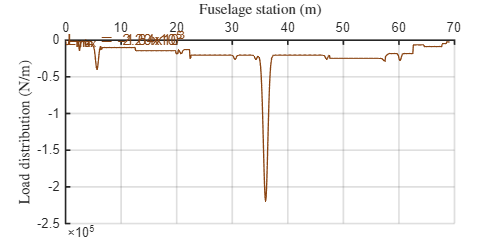

figure(1)

clf;

plot(x_stations, -W_total*g, '-', 'Color', [139/255 69/255 19/255], 'LineWidth', 1)

txt1 = 'L_{max} = -1.64x10^3';
txt2 = 'L_{min} = -2.20x10^5';

text(0, 0, txt1, 'Color', [139/255 69/255 19/255], 'FontSize', 11)
text(0, 0, txt2, 'Color', [139/255 69/255 19/255], 'FontSize', 11)

% Axis labels with LaTeX font
xlabel('Fuselage station (m)', 'Interpreter', 'latex');
ylabel('Load distribution (N/m)', 'Interpreter', 'latex');

% Customize axis appearance
set(gca, 'FontSize', 10); % Set axis font size
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
ax.LineWidth = 1.25;
ax.Box = 'off';

% Set plot limits and grid
grid on;

% Set figure size
set(gcf, 'Position', [0 0 500 250]);

**1.15 Basic Check**

Check weight & CG position

W_total_kg = sum(W_total)*dx;
CG_total_m = sum(x_stations .* W_total)*dx / W_total_kg;
disp(['Total Mass = ', num2str(W_total_kg,'%8.1f'),' kg']);

Total Mass = 139786.4 kg


disp(['Fuselage Station CG = ', num2str(CG_total_m,'%4.2f'),' m']);

Fuselage Station CG = 37.00 m


W_total_N = W_total_kg * g

W_total_N = 1.3708e+06

W_total_N * 3.75

ans = 5.1406e+06

### **2 Inertia Load**

Suppose we treat the fuselage as a beam supported at two points:

x_sparFront, x_sparRear

We find R_sparFront_kg, R_sparRear_kg so that sum of forces & moments = 0.

% Moment about x=0 (nose):
M_nose_kgm = sum(W_total .* x_stations)*dx;  % in (kg·m), if w_total is (kg/m)

% Example front & rear spar locations
LE = 26.5 - fuselage_start;
TE = 39.5 - fuselage_start;

x_sparFront = (LE + (TE-LE) * 0.2)  % old "Rf_loc"

x_sparFront = 26.6000

x_sparRear  = (LE + (TE-LE) * 0.7)  % old "Rr_loc"

x_sparRear = 33.1000

1) R_sparFront + R_sparRear = W_total_kg

2) x_sparFront*R_sparFront + x_sparRear*R_sparRear = M_nose_kgm

% Matrix form => [ -x_sparRear, -x_sparFront; -1, -1 ] * [R_rear; R_front] = [ -M; -W ]
A_spars = [-x_sparRear, -x_sparFront; -1 , -1];
b_spars = [-M_nose_kgm; -W_total_kg];

reactions_spar = A_spars \ b_spars; 

% [R_sparRear_kg; R_sparFront_kg] 
R_sparRear_kg  = reactions_spar(1);
R_sparFront_kg = reactions_spar(2);

disp('--- Spar Reaction Forces (mass, kg) about x=0 ---');

--- Spar Reaction Forces (mass, kg) about x=0 ---


disp(['R_sparRear_kg  = ', num2str(R_sparRear_kg,'%8.2f')]);

R_sparRear_kg  = 223628.88


disp(['R_sparFront_kg = ', num2str(R_sparFront_kg,'%8.2f')]);

R_sparFront_kg = -83842.48


R_sparFront_N = R_sparFront_kg * g

R_sparFront_N = -8.2221e+05

R_sparRear_N = R_sparRear_kg * g

R_sparRear_N = 2.1931e+06

### **3 Air Load**

Tailplane load T_tail_N acts at x_tail. 

Sum of forces: R_sparFront_N + R_sparRear_N + T_tail_N = 0

Sum of moments about x=0: R_sparFront_N*x_sparFront + R_sparRear_N*x_sparRear + T_tail_N*x_tail = 0

x_tail   = 70 - fuselage_start    % (m)

x_tail = 67.5000

T_tail_N = -54351;  % negative => downward

% Solve similarly:
% R_sparRear_N = -T_tail_N - R_sparFront_N, etc.

% For brevity, let's just show a solution form:
R_sparFront_N_tail = - T_tail_N * ((x_tail - x_sparRear)/(x_sparFront - x_sparRear));
R_sparRear_N_tail  = - T_tail_N - R_sparFront_N_tail;

disp('--- Tailplane Load Reactions on Two Spars ---');

--- Tailplane Load Reactions on Two Spars ---


disp(['Tail load = ', num2str(T_tail_N),' N (negative => downward)']);

Tail load = -54351 N (negative => downward)


disp(['R_sparFront_N = ', num2str(R_sparFront_N_tail,'%8.2f'),' N']);

R_sparFront_N = -287642.22 N


disp(['R_sparRear_N  = ', num2str(R_sparRear_N_tail,'%8.2f'),' N']);

R_sparRear_N  = 341993.22 N


### A Symetric Loading

**A1 Positive Ultimate Load**

n = 3.75

R_sparFront_n1 = R_sparFront_N * 3.75

R_sparFront_n1 = -3.0833e+06

R_sparRear_n1 = R_sparRear_N * 3.75

R_sparRear_n1 = 8.2239e+06

W_total_n1 = W_total .* 3.75 .* g

W_total_n1 = 1.0e+05 *

    0.0000    0.2184    0.2184    0.2184    0.2184    0.2184    0.0603    0.0603    0.0603    0.0603    0.0603    0.0603    0.0603    0.0603    0.0603    0.0603    0.0603    0.0603    0.0603    0.0603    0.0603    0.0604    0.0657    0.1259    0.3546    0.5456    0.3546    0.1259    0.0657    0.0604    0.0603    0.0603    0.0603    0.0603    0.0603    0.0603    0.2210    0.2210    0.2210    0.2210    0.2210    0.2210    0.2210    0.2210    0.2210    0.2210    0.2213    0.2226    0.2270    0.2730


sum(W_total_n1) * dx

ans = 5.1406e+06

R_sparFront_n2 = R_sparFront_N_tail * 3.75

R_sparFront_n2 = -1.0787e+06

R_sparRear_n2 = R_sparRear_N_tail * 3.75

R_sparRear_n2 = 1.2825e+06

T_tail_n2 = T_tail_N * 3.75

T_tail_n2 = -2.0382e+05

**A2 Negative Ultimate Load**

n = -1.5

R_sparFront_neg1 = R_sparFront_N * -1.5

R_sparFront_neg1 = 1.2333e+06

R_sparRear_neg1 = R_sparRear_N * -1.5

R_sparRear_neg1 = -3.2896e+06

W_total_neg1 = W_total .* -1.5 .* g

W_total_neg1 = 1.0e+05 *

   -0.0000   -0.0873   -0.0873   -0.0873   -0.0873   -0.0873   -0.0241   -0.0241   -0.0241   -0.0241   -0.0241   -0.0241   -0.0241   -0.0241   -0.0241   -0.0241   -0.0241   -0.0241   -0.0241   -0.0241   -0.0241   -0.0242   -0.0263   -0.0504   -0.1418   -0.2182   -0.1418   -0.0504   -0.0263   -0.0242   -0.0241   -0.0241   -0.0241   -0.0241   -0.0241   -0.0241   -0.0884   -0.0884   -0.0884   -0.0884   -0.0884   -0.0884   -0.0884   -0.0884   -0.0884   -0.0884   -0.0885   -0.0890   -0.0908   -0.1092


sum(W_total_neg1) * dx

ans = -2.0563e+06

R_sparFront_neg2 = R_sparFront_N_tail * -1.5

R_sparFront_neg2 = 4.3146e+05

R_sparRear_neg2 = R_sparRear_N_tail * -1.5

R_sparRear_neg2 = -5.1299e+05

T_tail_neg2 = T_tail_N * -1.5

T_tail_neg2 = 8.1526e+04

### B Nose-gear-off Landing

n = 2.8199

% Example load factor for on-ground (or maneuver)
n_land = 2.8199;  

T_tail_N_land = 0;

R_sparFront_L = R_sparFront_N * n_land 

R_sparFront_L = -2.3186e+06

R_sparRear_L  = R_sparRear_N * n_land 

R_sparRear_L = 6.1842e+06

R_sparRear_L + R_sparFront_L

ans = 3.8656e+06

W_total_land = W_total .* n_land .* g;
sum(W_total_land .* dx)

ans = 3.8656e+06

### **C OEI**

Fmax = 286.6e3;
engine1 = 0.27;
engine2 = 0.62;
b = 65;
ye = b/2*engine2;

xle = 26.5;
xac = xle + 10.1;
xe = 31.3;
xvtac = xac + 30.7;
dx_e = xvtac - xe;

Fy = Fmax*ye/dx_e

Fy = 1.6042e+05

### D Stored value

Sym = zeros(7, length(x_stations));
Sym(1, :) = x_stations;
Sym(2, :) = W_total_n1 .* dx;
Sym(3, 267) = R_sparFront_n1;
Sym(4, 332) = R_sparRear_n1;
Sym(5, 267) = R_sparFront_n2;
Sym(6, 332) = R_sparRear_n2;
Sym(7, 676) = T_tail_n2;

Sym_neg = zeros(7, length(x_stations));
Sym_neg(1, :) = x_stations;
Sym_neg(2, :) = W_total_neg1 .* dx;
Sym_neg(3, 267) = R_sparFront_neg1;
Sym_neg(4, 332) = R_sparRear_neg1;
Sym_neg(5, 267) = R_sparFront_neg2;
Sym_neg(6, 332) = R_sparRear_neg2;
Sym_neg(7, 676) = T_tail_neg2;

Landing = zeros(3, length(x_stations));
Landing(1, :) = x_stations;
Landing(2, :) = W_total_land .* dx;
Landing(3, 267) = R_sparFront_L;
Landing(4, 332) = R_sparRear_L;

OEI = zeros(2, length(x_stations));
OEI(1, :) = x_stations;
OEI(2, :) = W_total .* dx .* g;
OEI(3, 267) = R_sparFront_N;
OEI(4, 332) = R_sparRear_N;
OEI(5, 267) = R_sparFront_N_tail;
OEI(6, 332) = R_sparRear_N_tail;
OEI(7, 676) = T_tail_N;
OEI(8, 650) = Fy;

save('Case.mat', 'Sym', 'Sym_neg', 'Landing', 'OEI')

### **E Plotting**

figure(2)

clf;

R_sparFront_n1

R_sparFront_n1 = -3.0833e+06

R_sparRear_n1

R_sparRear_n1 = 8.2239e+06

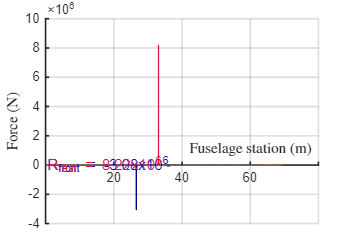


plot(x_stations, -W_total_n1 .* dx, '-', 'Color', [139/255 69/255 19/255], 'LineWidth', 1)
hold on
plot([x_stations(267) x_stations(267)], [0 R_sparFront_n1], '-', 'Color', [0/255 0/255 128/255], 'LineWidth', 1)
hold on
plot([x_stations(332) x_stations(332)], [0 R_sparRear_n1], '-', 'Color', [220/255 20/255 60/255], 'LineWidth', 1)
hold off

txt1 = 'R_{front} = -3.08x10^6';
txt2 = 'R_{rear} = 8.22x10^6';

text(0, 0, txt1, 'Color', [0/255 0/255 205/255], 'FontSize', 11)
text(0, 0, txt2, 'Color', [220/255 20/255 60/255], 'FontSize', 11)

% Axis labels with LaTeX font
xlabel('Fuselage station (m)', 'Interpreter', 'latex');
ylabel('Force (N)', 'Interpreter', 'latex');

% Customize axis appearance
set(gca, 'FontSize', 10); % Set axis font size
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
ax.LineWidth = 1.25;
ax.Box = 'off';

% Set plot limits and grid
grid on;

% Set figure size
set(gcf, 'Position', [0 0 350 250]);

figure(3)

clf;

T_tail_n2

T_tail_n2 = -2.0382e+05


R_sparFront_n2

R_sparFront_n2 = -1.0787e+06

R_sparRear_n2

R_sparRear_n2 = 1.2825e+06

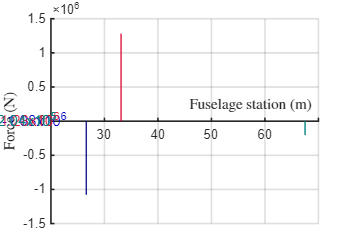


plot([x_stations(676) x_stations(676)], [0 T_tail_n2], '-', 'Color', [0/255 128/255 128/255], 'LineWidth', 1)
hold on
plot([x_stations(267) x_stations(267)], [0 R_sparFront_n2], '-', 'Color', [0/255 0/255 128/255], 'LineWidth', 1)
hold on
plot([x_stations(332) x_stations(332)], [0 R_sparRear_n2], '-', 'Color', [220/255 20/255 60/255], 'LineWidth', 1)
hold off

txt1 = 'R_{front} = -1.08x10^6';
txt2 = 'R_{rear} = 1.28x10^6';
txt3 = 'L_{tail} = -2.04x10^5';

text(0, 0, txt1, 'Color', [0/255 0/255 205/255], 'FontSize', 11)
text(0, 0, txt2, 'Color', [220/255 20/255 60/255], 'FontSize', 11)
text(0, 0, txt3, 'Color', [0/255 128/255 128/255], 'FontSize', 11)

% Axis labels with LaTeX font
xlabel('Fuselage station (m)', 'Interpreter', 'latex');
ylabel('Force (N)', 'Interpreter', 'latex');

% Customize axis appearance
set(gca, 'FontSize', 10); % Set axis font size
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
ax.LineWidth = 1.25;
ax.Box = 'off';

% Set plot limits and grid
grid on;

% Set figure size
set(gcf, 'Position', [0 0 350 250]);

figure(4)

clf;

R_sparFront_neg1

R_sparFront_neg1 = 1.2333e+06

R_sparRear_neg1

R_sparRear_neg1 = -3.2896e+06

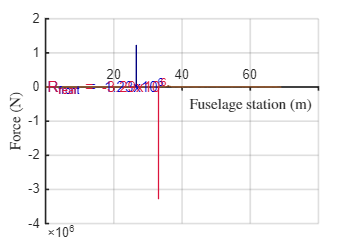


plot(x_stations, -W_total_neg1 .* dx, '-', 'Color', [139/255 69/255 19/255], 'LineWidth', 1)
hold on
plot([x_stations(267) x_stations(267)], [0 R_sparFront_neg1], '-', 'Color', [0/255 0/255 128/255], 'LineWidth', 1)
hold on
plot([x_stations(332) x_stations(332)], [0 R_sparRear_neg1], '-', 'Color', [220/255 20/255 60/255], 'LineWidth', 1)
hold off

txt1 = 'R_{front} = 1.23x10^6';
txt2 = 'R_{rear} = -3.29x10^6';

text(0, 0, txt1, 'Color', [0/255 0/255 205/255], 'FontSize', 11)
text(0, 0, txt2, 'Color', [220/255 20/255 60/255], 'FontSize', 11)

% Axis labels with LaTeX font
xlabel('Fuselage station (m)', 'Interpreter', 'latex');
ylabel('Force (N)', 'Interpreter', 'latex');

% Customize axis appearance
set(gca, 'FontSize', 10); % Set axis font size
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
ax.LineWidth = 1.25;
ax.Box = 'off';

% Set plot limits and grid
grid on;

% Set figure size
set(gcf, 'Position', [0 0 350 250]);

figure(5)

clf;

T_tail_neg2

T_tail_neg2 = 8.1526e+04


R_sparFront_neg2

R_sparFront_neg2 = 4.3146e+05

R_sparRear_neg2

R_sparRear_neg2 = -5.1299e+05

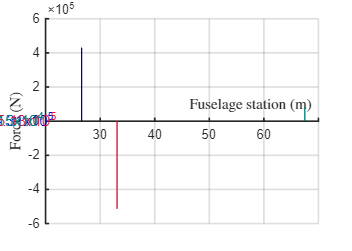


plot([x_stations(676) x_stations(676)], [0 T_tail_neg2], '-', 'Color', [0/255 128/255 128/255], 'LineWidth', 1)
hold on
plot([x_stations(267) x_stations(267)], [0 R_sparFront_neg2], '-', 'Color', [0/255 0/255 128/255], 'LineWidth', 1)
hold on
plot([x_stations(332) x_stations(332)], [0 R_sparRear_neg2], '-', 'Color', [220/255 20/255 60/255], 'LineWidth', 1)
hold off

txt1 = 'R_{front} = 4.31x10^5';
txt2 = 'R_{rear} = -5.13x10^5';
txt3 = 'L_{tail} = 8.15x10^4';

text(0, 0, txt1, 'Color', [0/255 0/255 205/255], 'FontSize', 11)
text(0, 0, txt2, 'Color', [220/255 20/255 60/255], 'FontSize', 11)
text(0, 0, txt3, 'Color', [0/255 128/255 128/255], 'FontSize', 11)

% Axis labels with LaTeX font
xlabel('Fuselage station (m)', 'Interpreter', 'latex');
ylabel('Force (N)', 'Interpreter', 'latex');

% Customize axis appearance
set(gca, 'FontSize', 10); % Set axis font size
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
ax.LineWidth = 1.25;
ax.Box = 'off';

% Set plot limits and grid
grid on;

% Set figure size
set(gcf, 'Position', [0 0 350 250]);

figure(6)

clf;

R_sparFront_L

R_sparFront_L = -2.3186e+06

R_sparRear_L

R_sparRear_L = 6.1842e+06

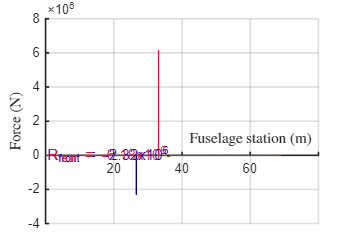


plot(x_stations, -W_total_land .* dx, '-', 'Color', [139/255 69/255 19/255], 'LineWidth', 1)
hold on
plot([x_stations(267) x_stations(267)], [0 R_sparFront_L], '-', 'Color', [0/255 0/255 128/255], 'LineWidth', 1)
hold on
plot([x_stations(332) x_stations(332)], [0 R_sparRear_L], '-', 'Color', [220/255 20/255 60/255], 'LineWidth', 1)
hold off

txt1 = 'R_{front} = -2.32x10^6';
txt2 = 'R_{rear} = -6.18x10^6';

text(0, 0, txt1, 'Color', [0/255 0/255 205/255], 'FontSize', 11)
text(0, 0, txt2, 'Color', [220/255 20/255 60/255], 'FontSize', 11)

% Axis labels with LaTeX font
xlabel('Fuselage station (m)', 'Interpreter', 'latex');
ylabel('Force (N)', 'Interpreter', 'latex');

% Customize axis appearance
set(gca, 'FontSize', 10); % Set axis font size
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
ax.LineWidth = 1.25;
ax.Box = 'off';

% Set plot limits and grid
grid on;

% Set figure size
set(gcf, 'Position', [0 0 350 250]);

figure(7)

clf;

R_sparFront_N

R_sparFront_N = -8.2221e+05

R_sparRear_N

R_sparRear_N = 2.1931e+06

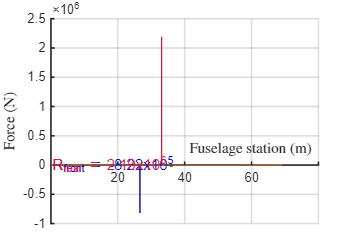


plot(x_stations, -W_total .* g .* dx, '-', 'Color', [139/255 69/255 19/255], 'LineWidth', 1)
hold on
plot([x_stations(267) x_stations(267)], [0 R_sparFront_N], '-', 'Color', [0/255 0/255 128/255], 'LineWidth', 1)
hold on
plot([x_stations(332) x_stations(332)], [0 R_sparRear_N], '-', 'Color', [220/255 20/255 60/255], 'LineWidth', 1)
hold off

txt1 = 'R_{front} = -8.22x10^5';
txt2 = 'R_{rear} = 2.19x10^6';

text(0, 0, txt1, 'Color', [0/255 0/255 205/255], 'FontSize', 11)
text(0, 0, txt2, 'Color', [220/255 20/255 60/255], 'FontSize', 11)

% Axis labels with LaTeX font
xlabel('Fuselage station (m)', 'Interpreter', 'latex');
ylabel('Force (N)', 'Interpreter', 'latex');

% Customize axis appearance
set(gca, 'FontSize', 10); % Set axis font size
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
ax.LineWidth = 1.25;
ax.Box = 'off';

% Set plot limits and grid
grid on;

% Set figure size
set(gcf, 'Position', [0 0 350 250]);

figure(8)

clf;

T_tail_N

T_tail_N = -54351

R_sparFront_N_tail

R_sparFront_N_tail = -2.8764e+05

R_sparRear_N_tail

R_sparRear_N_tail = 3.4199e+05

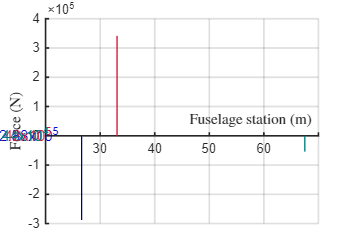


plot([x_stations(676) x_stations(676)], [0 T_tail_N], '-', 'Color', [0/255 128/255 128/255], 'LineWidth', 1)
hold on
plot([x_stations(267) x_stations(267)], [0 R_sparFront_N_tail], '-', 'Color', [0/255 0/255 128/255], 'LineWidth', 1)
hold on
plot([x_stations(332) x_stations(332)], [0 R_sparRear_N_tail], '-', 'Color', [220/255 20/255 60/255], 'LineWidth', 1)
hold off

txt1 = 'R_{front} = -2.88x10^5';
txt2 = 'R_{rear} = 3.42x10^5';
txt3 = 'L_{tail} = -5.44x10^4';

text(0, 0, txt1, 'Color', [0/255 0/255 205/255], 'FontSize', 11)
text(0, 0, txt2, 'Color', [220/255 20/255 60/255], 'FontSize', 11)
text(0, 0, txt3, 'Color', [0/255 128/255 128/255], 'FontSize', 11)

% Axis labels with LaTeX font
xlabel('Fuselage station (m)', 'Interpreter', 'latex');
ylabel('Force (N)', 'Interpreter', 'latex');

% Customize axis appearance
set(gca, 'FontSize', 10); % Set axis font size
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
ax.LineWidth = 1.25;
ax.Box = 'off';

% Set plot limits and grid
grid on;

% Set figure size
set(gcf, 'Position', [0 0 350 250]);